IOT_signal generation 

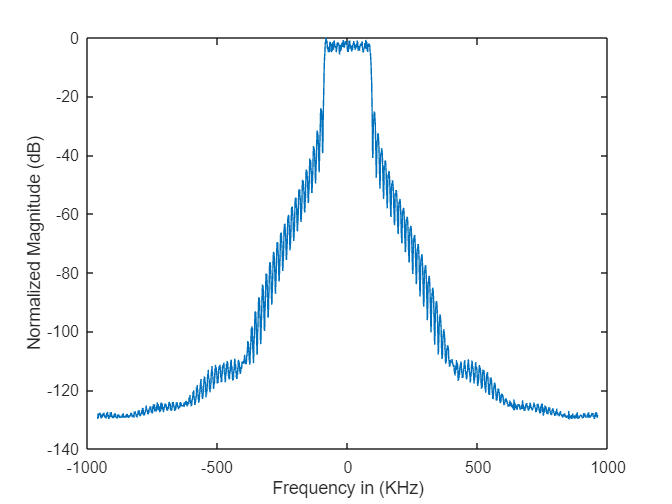

% generator 
clc; clear; close all;
% plot the magnitude spectrum of the baseband signal.
[waveform1, Fs] = generate_NBiot_UL();
[signal, f] = pwelch(waveform1, 2048, 1024, 2048, Fs);
signal1 = signal / max(abs(signal));       %NB-IOT signal

% second signal
[waveform2, Fs] = generate_NBiot_UL();
[signal2, f] = pwelch(waveform2, 2048, 1024, 2048, Fs);
signal2 = signal2 / max(abs(signal2));

%3rd sig
[waveform3, Fs] = generate_NBiot_UL();
[signal3, f] = pwelch(waveform2, 2048, 1024, 2048, Fs);
signal3 = signal3 / max(abs(signal3));

%4th sig
[waveform4, Fs] = generate_NBiot_UL();
[signal4, f] = pwelch(waveform2, 2048, 1024, 2048, Fs);
signal4 = signal4 / max(abs(signal4));

%5th signal:
[waveform5, Fs] = generate_NBiot_UL();
[signal5, f] = pwelch(waveform2, 2048, 1024, 2048, Fs);
signal5 = signal5 / max(abs(signal5));

%6th signal:
[waveform6, Fs] = generate_NBiot_UL();
[signal6, f] = pwelch(waveform2, 2048, 1024, 2048, Fs);
signal6 = signal6 / max(abs(signal6));



% Create a modified frequency vector centered around 0
f_modified = linspace(-Fs / 2, Fs / 2, length(f));

figure;
plot(f_modified / 1e3, 20 * log10(fftshift(signal1)))
xlabel('Frequency in (KHz)')
ylabel('Normalized Magnitude (dB)') 
xlim([-1000, 1000]); % Set x-axis limits

Transmitter:

upsampling -> LPF -> DUC

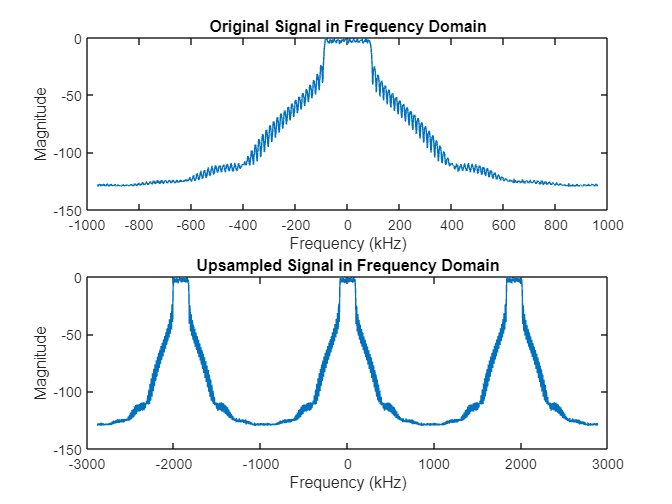

%% upsampling:
upsampling_factor = 3;

% Upsample the 1st sig
signal_time1= ifft(signal1); % signal1 in  time domain
upsampled_signal1 = upsample(signal_time1, upsampling_factor);

% Upsample the 2nd sig
signal_time2= ifft(signal2); % signal2 in  time domain
upsampled_signal2 = upsample(signal_time2, upsampling_factor);

% Upsample the 3rd sig
signal_time3= ifft(signal3); % signal3 in  time domain
upsampled_signal3 = upsample(signal_time3, upsampling_factor);

% Upsample the 4th sig
signal_time4= ifft(signal4); % signal4 in  time domain
upsampled_signal4 = upsample(signal_time4, upsampling_factor);

% Upsample the 5th sig
signal_time5= ifft(signal5); % signal5 in  time domain
upsampled_signal5 = upsample(signal_time5, upsampling_factor);

% Upsample the 6th sig
signal_time6= ifft(signal6); % signal6 in  time domain
upsampled_signal6 = upsample(signal_time6, upsampling_factor);


% Adjust the sampling rate accordingly
new_sampling_rate = Fs * upsampling_factor;

% plotting the first upsampled signal:
% Compute the FFT of the original signal
original_fft = fft(signal_time1);

% Compute the FFT of the upsampled signal
upsampled_fft1 = fft(upsampled_signal1);

% Create frequency vectors for the FFT results
f_modified = linspace(-Fs / 2, Fs / 2, length(f));
upsampled_freq = linspace(-new_sampling_rate/2, new_sampling_rate/2, length(upsampled_fft1));


% Plot the original signal 
figure;
subplot(2, 1, 1);
plot(f_modified / 1e3, 20 * log10(fftshift(signal1)));
title('Original Signal in Frequency Domain');
xlabel('Frequency (kHz)');
ylabel('Magnitude');


% Plot the upsampled signal_1
subplot(2, 1, 2);
plot(upsampled_freq / 1e3, 20 * log10(abs(fftshift((upsampled_fft1)))));
title('Upsampled Signal in Frequency Domain');
xlabel('Frequency (kHz)');
ylabel('Magnitude');

# FIR LPF Transmation Filter

Designing The Filter 

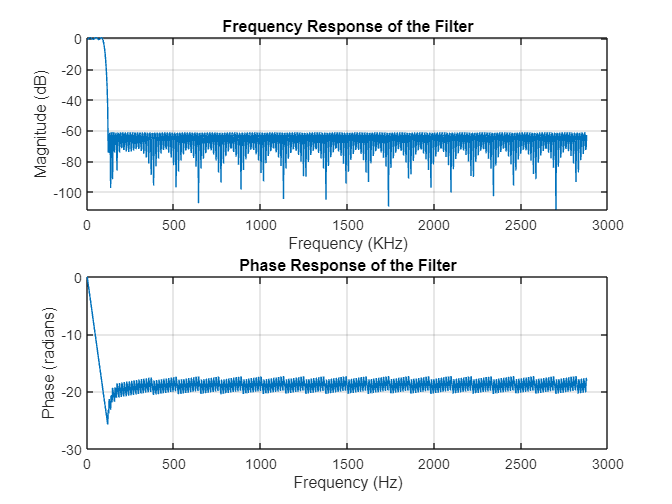

%LPF Filter Paramaters: 
% Filter coeffecients-> conv, impulse response-> mult
% passband ripples=1 db , stopband attenuation = 80 db
% Passband Frequency = 90KHZ, Stopband Frequency =120KHZ
% and number of filter taps =400  

% Load the filter coefficients
load('TFCOFF.mat'); 
% Calculate the frequency response of the filter
[h, fl] = freqz(TF, 1, 1024, 'half'); 

% Convert frequency to Hz assuming a sampling rate, Fs
fl = fl * (new_sampling_rate / (2*pi));

% Plot the magnitude response in dB
figure;
subplot(2,1,1)
plot(fl/1e3, 20*log10(abs(h)));
xlabel('Frequency (KHz)');
ylabel('Magnitude (dB)');
title('Frequency Response of the Filter');
grid on;

% Plot the phase response
subplot(2,1,2)
plot(fl/1e3, unwrap(angle(h)));
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
title('Phase Response of the Filter');
grid on;

# Applying the filter 

% Prepare a frequency vector
f = linspace(-new_sampling_rate/2, new_sampling_rate/2, length(upsampled_signal6));
    
% Load the filter coefficients
load('TFCOFF.mat');
upsampled_signals=[upsampled_signal1 upsampled_signal1  upsampled_signal2 upsampled_signal3 upsampled_signal4 upsampled_signal5 upsampled_signal6];

% Preallocate a matrix to store the filtered signals
filtered_signals = zeros(size(upsampled_signals));

% Loop through the upsampled signals
for i = 1:size(upsampled_signals, 2)
    % Apply the filter to each signal
    filtered_signal = filter(TF, 1, upsampled_signals(:, i));
    
    % Store the filtered signal in the matrix
    filtered_signals(:, i) = filtered_signal;

end


# Plotting The First Filtered Signal 

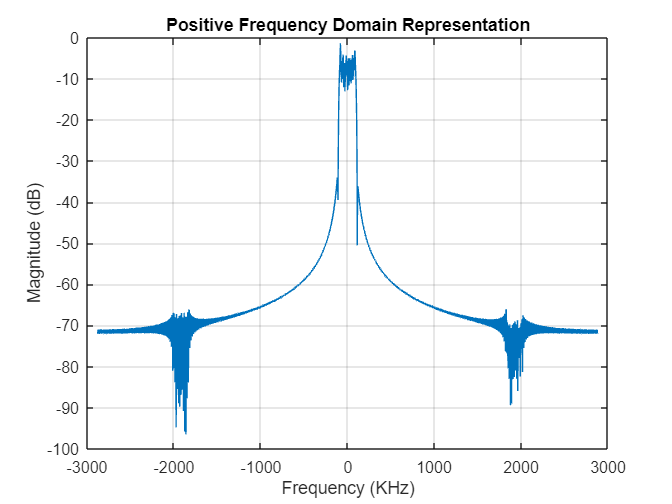

% filtered_signal1 = filter(TF, 1, upsampled_signal1);
filtered_signal_freq_domain = fftshift(fft(filtered_signals(:, 2)));
% Get the magnitude in dB for the positive half
filtered_signal_freq_domain_in_db = 20 * log10(abs(filtered_signal_freq_domain));
% Plot the positive half of the spectrum
figure;
plot(f/1e3, filtered_signal_freq_domain_in_db);
title('Positive Frequency Domain Representation');
xlabel('Frequency (KHz)');
ylabel('Magnitude (dB)');
grid on;

# Digital Up Converstion 

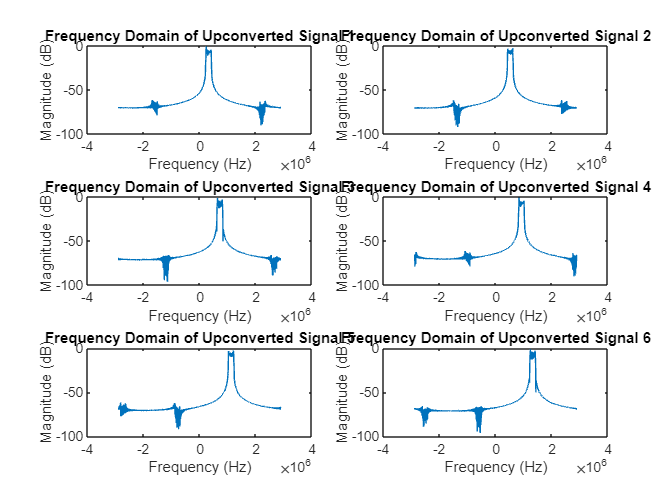

% upconvertion 
t = (0:length(upsampled_signal1)-1)' / new_sampling_rate;
% Define the center frequencies relative to the intermediate frequency
freqs = [320 520 720 920 1120 1320] * 1e3;

% Use bsxfun to create the carriers matrix, each column corresponding to one frequency
carriers = bsxfun(@(t, freq) exp(1j * 2 * pi * freq * t), t, freqs);

% Initialize upconverted signals matrix
upconvertedSignals = zeros(length(upsampled_signal1), length(freqs));

% Upconvert each signal
for i = 1:length(freqs)
    % Multiply the filtered signal with the corresponding carrier
    upconvertedSignals(:, i) = filtered_signals(:,i) .* carriers(:, i); % Replace filtered_signal1 with the appropriate signal variable for each i
end


figure
for i = 1:length(freqs)
    fftSignal = fftshift(fft(upconvertedSignals(:, i)));
    subplot(3, 2, i);
    plot(f, 20 * log10(abs(fftSignal)));
    title(['Frequency Domain of Upconverted Signal ' num2str(i)]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
end

# Summing All The Signals 

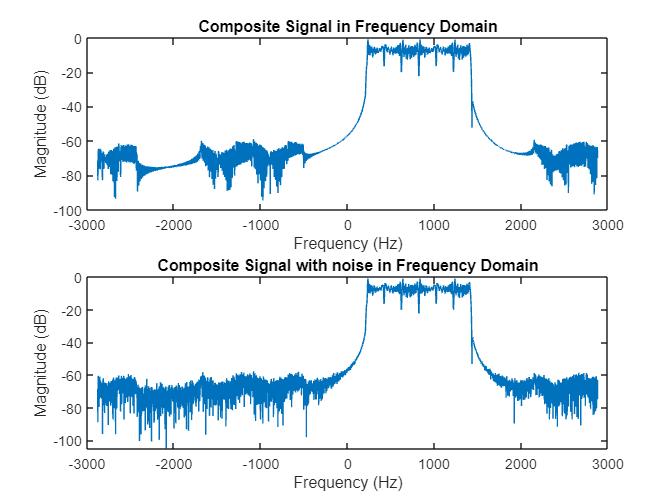


% Initialize the summed signal
compositeSignal = zeros(size(upconvertedSignals, 1), 1);

% Perform the summation using a for loop
for i = 1:6
    compositeSignal = compositeSignal + upconvertedSignals(:, i);
end

figure
% plot the signal
subplot(2,1,1)
plot(f/1e3, 20*log10(abs(fftshift(fft(compositeSignal)))));
title('Composite Signal in Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

% noise 
desiredSNR_dB = 60;  % For example, 20 dB

% Add AWGN to the composite signal 
compositeSignalWithNoise = awgn(compositeSignal, desiredSNR_dB, 'measured');

subplot(2,1,2)
plot(f/1e3, 20*log10(abs(fftshift(fft(compositeSignalWithNoise)))));
title('Composite Signal with noise in Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

# Digital Down Converstion 

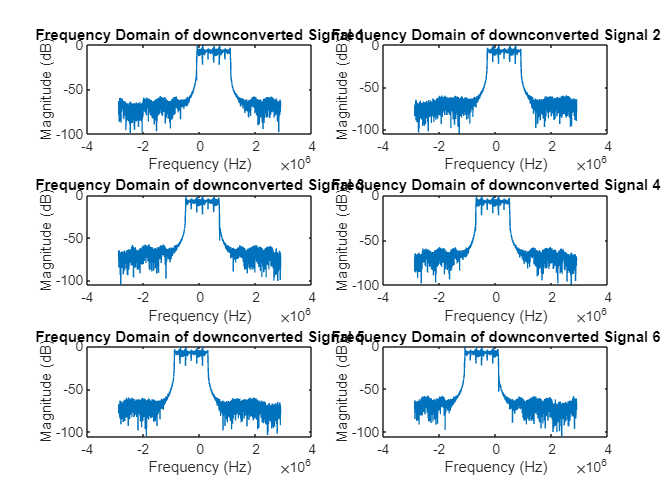

% down convertion 
% Initialize upconverted signals matrix
downconvertedSignals = zeros(length(upsampled_signal1), length(freqs));
for i = 1:length(freqs)
    % Multiply the composite signal with noise with the complex conjugate of the corresponding carrier
    downconvertedSignals(:, i) = compositeSignalWithNoise .* conj(carriers(:, i));
end


figure
% Plot the frequency domain of the upconverted signals
for i = 1:length(freqs)
    fftSignal = fftshift(fft(downconvertedSignals(:, i)));
    subplot(3, 2, i);
    plot(f, 20 * log10(abs(fftSignal)));
    title(['Frequency Domain of downconverted Signal ' num2str(i)]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
end

# 4. Problem Defination:

**The task is to design a digital FIR filter to selectively extract a Narrowband IoT (NB-IoT) signal from a mixed signal at an intermediate frequency. The filter should allow this specific signal to pass with little alteration while effectively suppressing any undesired signals. It must also support down-sampling of the signal after filtering, requiring a design that prevents aliasing. The design challenge lies in achieving a balance between the filter's accuracy and the computational effort required.**

# 5. Determining the Filter Specifications and Constraints:

**For the digital FIR filter design, the specifications and constraints are as follows:**

- **Passband Ripples: This should be minimal to ensure the integrity of the NB-IoT signal; typically, a ripple less than 1 dB is acceptable.**

- **Stopband Attenuation: To effectively isolate the desired signal, a high level of attenuation is needed for the other signals; a common benchmark is at least 60 dB.**

- **Transition Region Width: The width between the passband and stopband must be narrow enough to enable clear distinction of the desired signal and facilitate successful down-sampling, with the specific width depending on the adjacent signal frequencies.**

- **Number of Filter Taps: This directly relates to the complexity of the filter; more taps mean a sharper transition and better signal fidelity, but also increased computational demand. The number should be chosen based on the acceptable level of complexity for the application.**

# 6. Designing Prototype FIR Filters:

#### First prototype 

- Passband Frequency : 90 khz

- Stopband Frequency : 120KHz

- Passband Ripple: 1 dB

- Stopband Attenuation: 40 dB

- Number of Filter Taps: 50 taps

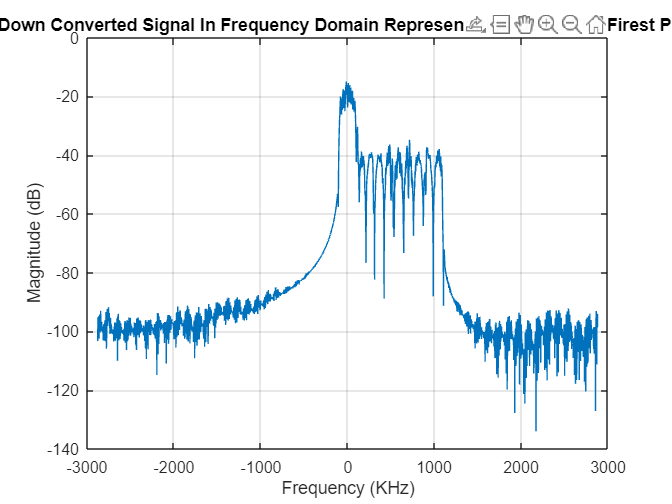


% Load the filter coefficients
load('RF1.mat'); 
first_downconverted_filtered_signal = filter(RF, 1, downconvertedSignals(:,1));
first_downconverted_signal = fft(first_downconverted_filtered_signal);
% Get the magnitude in dB for the positive half
first_downconverted_signal_in_db = 20 * log10(abs(first_downconverted_signal));
% Plot the positive half of the spectrum
figure;
plot(f/1e3, fftshift(first_downconverted_signal_in_db));
title('First Down Converted Signal In Frequency Domain Representation Using The Firest Prototype');
xlabel('Frequency (KHz)');
ylabel('Magnitude (dB)');
grid on;

The graph indicates that the filter has a significant attenuation in the stopband, which is desirable. However, the transition band between the passband and stopband isn't very sharp, suggesting that the filter may not sharply isolate the desired signal. 

#### Second prototype 

- Passband Frequency : 90 khz

- Stopband Frequency :100  KHz

- Passband Ripple: 1 dB

- Stopband Attenuation: 60 dB

- Number of Filter Taps: 100 taps

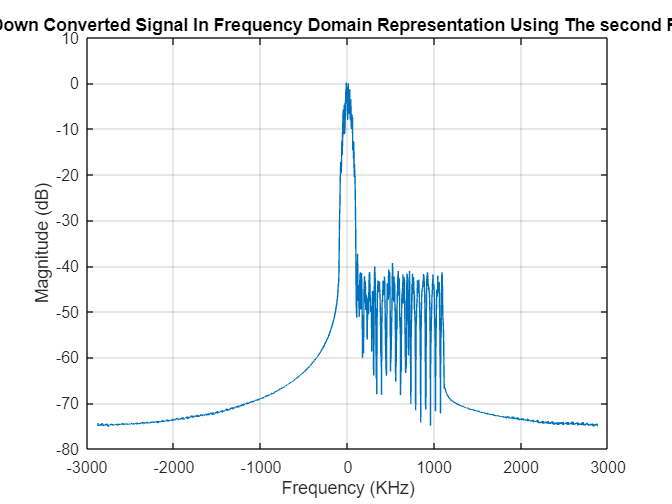

% Load the filter coefficients
load('RF2.mat'); 
first_downconverted_filtered_signal = filter(RF2, 1, downconvertedSignals(:,1));
first_downconverted_signal = fft(first_downconverted_filtered_signal);
% Get the magnitude in dB for the positive half
first_downconverted_signal_in_db = 20 * log10(abs(first_downconverted_signal));
% Plot the positive half of the spectrum
figure;
plot(f/1e3, fftshift(first_downconverted_signal_in_db));
title('First Down Converted Signal In Frequency Domain Representation Using The second Prototype');
xlabel('Frequency (KHz)');
ylabel('Magnitude (dB)');
grid on;

The frequency domain representation for the second prototype shows a prominent peak, which suggests effective filtering around the passband frequency of 90 kHz. The transition from passband to stopband appears to be quite rapid, indicating a potentially sharp cutoff, which aligns with the implementation of 100 filter taps. However, the plot also shows significant ripples in the stopband region, raising concerns about whether the 60 dB stopband attenuation specification has been met.  

#### Third  prototype 

- Passband Frequency : 90 khz

- Stopband Frequency :120  KHz

- Passband Ripple: 1 dB

- Stopband Attenuation: 80 dB

- Number of Filter Taps: 200 taps

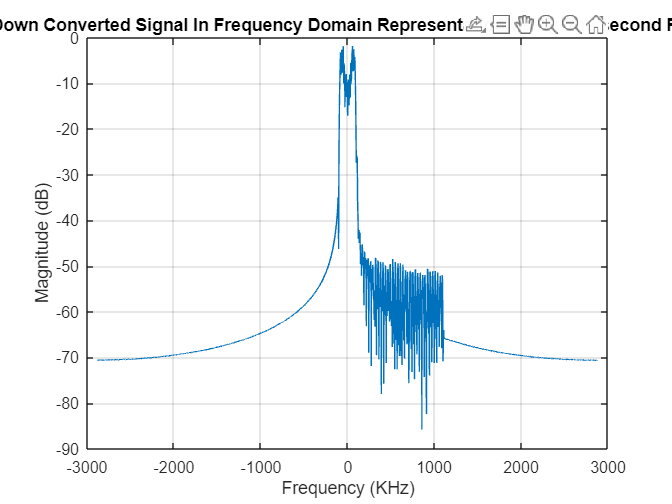

% Load the filter coefficients
load('RF3.mat'); 
first_downconverted_filtered_signal = filter(RF3, 1, downconvertedSignals(:,1));
first_downconverted_signal = fft(first_downconverted_filtered_signal);
% Get the magnitude in dB for the positive half
first_downconverted_signal_in_db = 20 * log10(abs(first_downconverted_signal));
% Plot the positive half of the spectrum
figure;
plot(f/1e3, fftshift(first_downconverted_signal_in_db));
title('First Down Converted Signal In Frequency Domain Representation Using The second Prototype');
xlabel('Frequency (KHz)');
ylabel('Magnitude (dB)');
grid on;

 for this prototype with a passband frequency at 90 kHz and a stopband starting at 120 kHz, paired with the substantial number of filter taps (200), suggests a design aimed at sharp transition characteristics and significant signal attenuation in the stopband. In terms of amplitude, the peak in the passband is well-defined, indicating a strong signal presence where expected. However, the amplitude drop into the stopband isn't as steep as one might expect with an 80 dB specification, as there is visible spectral leakage past the 90 kHz mark.

#### Fourth  prototype 

- Passband Frequency : 90 khz

- Stopband Frequency :110  KHz

- Passband Ripple: 1 dB

- Stopband Attenuation: 80 dB

- Number of Filter Taps: 500 taps

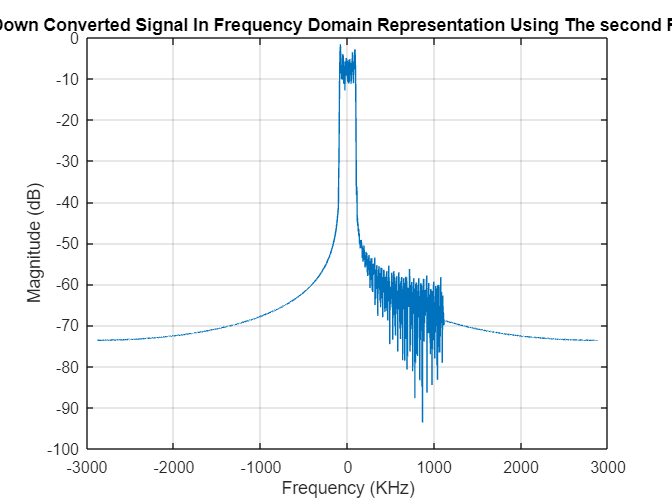

% Load the filter coefficients
load('RF4.mat'); 
first_downconverted_filtered_signal = filter(RF4, 1, downconvertedSignals(:,1));
first_downconverted_signal = fft(first_downconverted_filtered_signal);
% Get the magnitude in dB for the positive half
first_downconverted_signal_in_db = 20 * log10(abs(first_downconverted_signal));
% Plot the positive half of the spectrum
figure;
plot(f/1e3, fftshift(first_downconverted_signal_in_db));
title('First Down Converted Signal In Frequency Domain Representation Using The second Prototype');
xlabel('Frequency (KHz)');
ylabel('Magnitude (dB)');
grid on;

filter that is performing well in terms of isolating the desired frequency range. The amplitude of the signal peaks sharply at the passband frequency, indicating a strong and focused response where it is most desired. The transition to the stopband is very steep, as evidenced by the rapid drop in magnitude, which is consistent with the high number of taps used in the filter design.

# Applying The Chossen Filter 

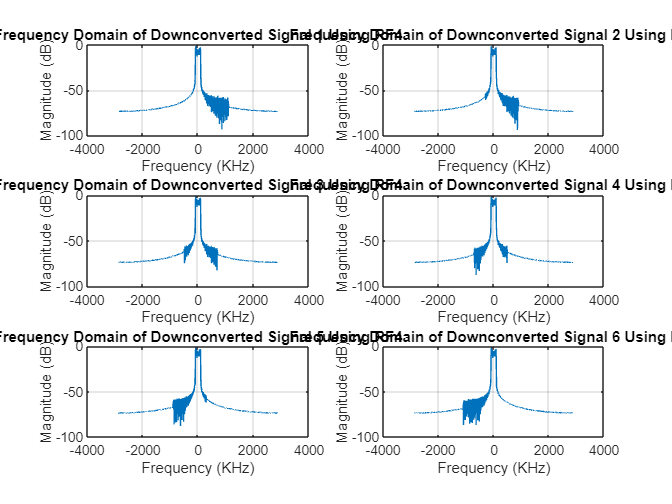

% Load the filter coefficients
load('RF4.mat'); 

% Assuming downconvertedSignals and new_sampling_rate are already defined
% Initialize a matrix to store the filtered signals
filtered_downconverted_signals = zeros(size(downconvertedSignals));

% Prepare a frequency vector for the positive frequencies only
f = linspace(-new_sampling_rate/2, new_sampling_rate/2, size(downconvertedSignals, 1));

% Initialize a figure for plotting
figure;

% Loop over all downconverted signals
for i = 1:size(downconvertedSignals, 2)
    % Apply the filter to each downconverted signal
    filtered_signal = filter(RF4, 1, downconvertedSignals(:, i));

    % Store the filtered signal
    filtered_downconverted_signals(:, i) = filtered_signal;

    % Compute FFT and convert to dB scale
    fft_signal = fft(filtered_signal);
    fft_signal_in_db = 20 * log10(abs(fft_signal));

    % Plot the frequency domain representation
    subplot(3, 2, i);
    plot(f/1e3, fftshift(fft_signal_in_db));
    title(['Frequency Domain of Downconverted Signal ' num2str(i) ' Using RF4']);
    xlabel('Frequency (KHz)');
    ylabel('Magnitude (dB)');
    grid on;
end

# Down Sampling 

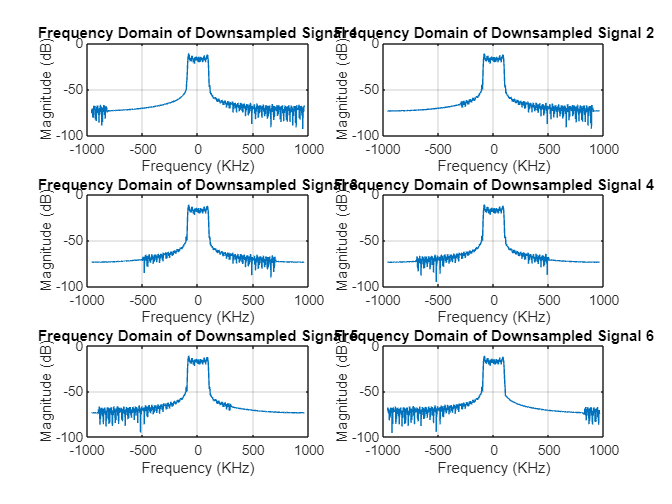

% Define the downsampling factor
downsampling_factor = 3;  % Example factor

% Initialize a matrix to store the downsampled signals
downsampled_signals = zeros(floor(size(filtered_downconverted_signals, 1) / downsampling_factor), size(filtered_downconverted_signals, 2));

% Initialize a figure for plotting
figure;

% Loop over all filtered downconverted signals
for i = 1:size(filtered_downconverted_signals, 2)
    % Downsample the signal by taking every Nth sample
    downsampled_signal = filtered_downconverted_signals(1:downsampling_factor:end, i);

    % Store the downsampled signal
    downsampled_signals(:, i) = downsampled_signal;

    % Compute FFT and convert to dB scale
    fft_downsampled_signal = fft(downsampled_signal);
    fft_downsampled_signal_in_db = 20 * log10(abs(fftshift(fft_downsampled_signal)));

    % Prepare a frequency vector for the downsampled signal
    downsampled_f = linspace(-new_sampling_rate/(2*downsampling_factor), new_sampling_rate/(2*downsampling_factor), length(fft_downsampled_signal));

    % Plot the frequency domain representation
    subplot(3, 2, i);
    plot(downsampled_f/1e3, fft_downsampled_signal_in_db);
    title(['Frequency Domain of Downsampled Signal ' num2str(i)]);
    xlabel('Frequency (KHz)');
    ylabel('Magnitude (dB)');
    grid on;
end

#  plot 3 spectra for one of the received NB-IoT waveforms

**a) Digital downconversion **

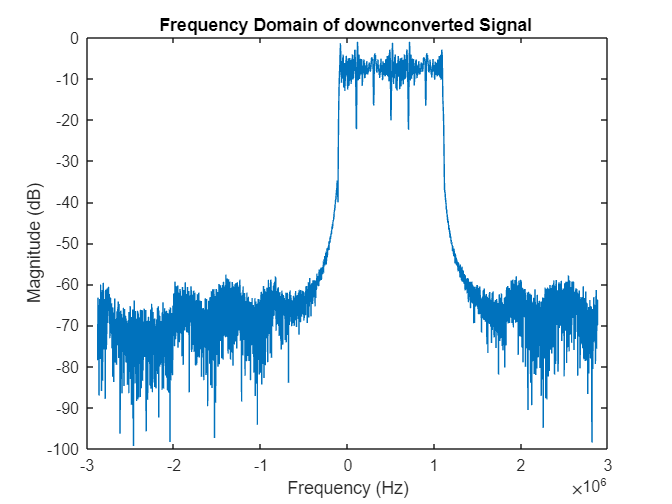

firstsignal=downconvertedSignals(:, 1);
fftSignal = fftshift(fft(firstsignal));
figure;
plot(f, 20 * log10(abs(fftSignal)))
title('Frequency Domain of downconverted Signal ');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

**b) Digital downconversion and FIR filtering**

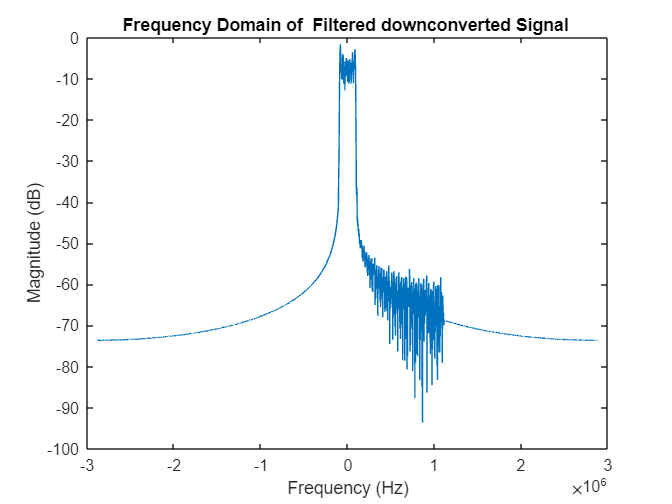

firstsignal=filtered_downconverted_signals(:, 1);
fftSignal = fftshift(fft(firstsignal));
figure;
plot(f, 20 * log10(abs(fftSignal)))
title('Frequency Domain of  Filtered downconverted Signal ');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

**c) Digital downconversion, FIR filtering, and downsampling.**

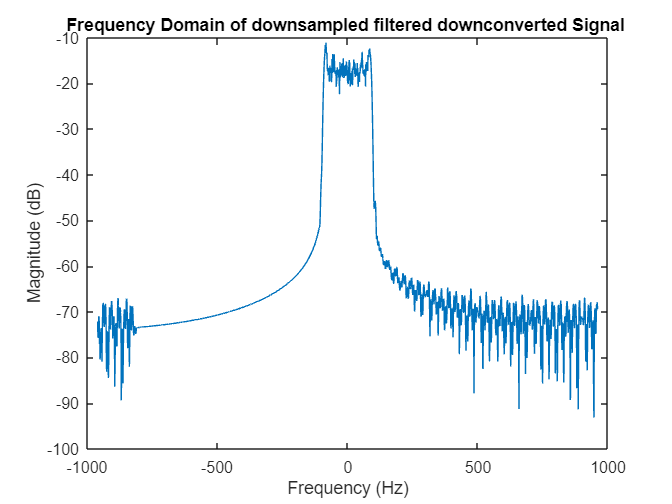

firstsignal=downsampled_signals(:, 1);
fftSignal = fftshift(fft(firstsignal));
figure;
plot(downsampled_f/1e3, 20 * log10(abs(fftSignal)))
title('Frequency Domain of downsampled filtered downconverted Signal ');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

Discuss public health, safety, as well as social, environmental, and economic factors

related to one or more NB-IoT applications of your choice.

References:

functions:

function [waveform,Fs]= generate_NBiot_UL()
tbs = 144;                          % The transport block size
totNumBlks = 10;                     % Number of simulated transport blocks
subspacing='15kHz';
ue = struct();                      % Initialize the UE structure
ue.NBULSubcarrierSpacing = subspacing ; % 3.75kHz, 15kHz
ue.NNCellID = 0;                    % Narrowband cell identity

chs = struct();
% NPUSCH carries data or control information
chs.NPUSCHFormat = 'Data'; % Payload type (Data or Control)
% The number of subcarriers used for NPUSCH 'NscRU' depends on the NPUSCH
% format and subcarrier spacing 'NBULSubcarrierSpacing' as shown in TS
% 36.211 Table 10.1.2.3-1. There are 1,3,6 or 12 contiguous subcarriers for
% NPUSCH
chs.NBULSubcarrierSet = 0:11;  % Range is 0-11 (15kHz); 0-47 (3.75kHz)
%chs.NRUsc = length(chs.NBULSubcarrierSet);
chs.NRUsc = 12;
chs.CyclicShift = 0;   % Cyclic shift required when NRUsc = 3 or 6
chs.RNTI = 0;          % RNTI value
chs.NLayers = 1;       % Number of layers
chs.NRU = 2;           % Number of resource units
chs.NRep = 4;          % Number of repetitions of the NPUSCH
chs.SlotIdx = 0;       % Start slot index in a bundle
% The symbol modulation depends on the NPUSCH format and NscRU as
% given by TS 36.211 Table 10.1.3.2-1
chs.Modulation = 'QPSK';
rvDCI = 0;             % RV offset signaled via DCI (See 36.213 16.5.1.2)

% Specify the NPUSCH and DM-RS power scaling in dB for plot visualization
chs.NPUSCHPower = 30;
chs.NPUSCHDRSPower = 34;

chs.SeqGroupHopping = 'on'; % Enable/Disable Sequence-Group Hopping for UE
chs.SeqGroup = 0;           % Delta_SS. Higher-layer parameter groupAssignmentNPUSCH

% Get number of time slots in a resource unit NULSlots according to
% TS 36.211 Table 10.1.2.3-1
if strcmpi(chs.NPUSCHFormat,'Data')
    if chs.NRUsc == 1
        %NULSlots = 16;
        NULSlots = 16;
    elseif any(chs.NRUsc == [3 6 12])
       NULSlots = 24/chs.NRUsc;
       % NULSlots = 2;

    else
        error('Invalid number of subcarriers. NRUsc must be one of 1,3,6,12');
    end
elseif strcmpi(chs.NPUSCHFormat,'Control')
    %NULSlots = 4;
            NULSlots = 4;

else
    error('Invalid NPUSCH Format (%s). NPUSCHFormat must be ''Data'' or ''Control''',chs.NPUSCHFormat);
end
chs.NULSlots = NULSlots;

NSlotsPerBundle = chs.NRU*chs.NULSlots*chs.NRep; % Number of slots in a codeword bundle
TotNSlots = totNumBlks*NSlotsPerBundle;   % Total number of simulated slots



% Initialize the random generator to default state
rng('default');

% Get the slot grid and number of slots per frame
emptySlotGrid = lteNBResourceGrid(ue);
slotGridSize = size(emptySlotGrid);
NSlotsPerFrame = 20/(slotGridSize(1)/12);

state = [];    % NPUSCH encoder and DM-RS state, auto re-initialization in the function
trblk = [];    % Initialize the transport block
txgrid = [];   % Full grid initialization

% Display the number of slots being generated
% fprintf('\nGenerating %d slots corresponding to %d transport block(s)\n',TotNSlots,totNumBlks);
for slotIdx = 0+(0:TotNSlots-1)
    % Calculate the frame number and slot number within the frame
    ue.NFrame = fix(slotIdx/NSlotsPerFrame);
    ue.NSlot = mod(slotIdx,NSlotsPerFrame);

    if isempty(trblk)
       if strcmpi(chs.NPUSCHFormat,'Data')
           % UL-SCH encoding is done for the two RV values used for
           % transmitting the codewords. The RV sequence used is determined
           % from the rvDCI value signaled in the DCI and alternates
           % between 0 and 2 as given in TS 36.213 Section 16.5.1.2

           % Define the transport block which will be encoded to create the
           % codewords for different RV
           trblk = randi([0 1],tbs,1);

           % Determine the coded transport block size
           [~, info] = lteNPUSCHIndices(ue,chs);
           outblklen = info.G;
           % Create the codewords corresponding to the two RV values used
           % in the first and second block, this will be repeated till all
           % blocks are transmitted
           chs.RV = 2*mod(rvDCI+0,2); % RV for the first block
           cw = lteNULSCH(chs,outblklen,trblk); % CRC and Turbo coding
           chs.RV = 2*mod(rvDCI+1,2); % RV for the second block
           cw = [cw lteNULSCH(chs,outblklen,trblk)]; %#ok<AGROW> % CRC and Turbo coding is repeated
       else
           trblk = randi([0 1],1); % 1 bit ACK
           % For ACK, the same codeword is transmitted every block as
           % defined in TS 36.212 Section 6.3.3
           cw = lteNULSCH(trblk);
       end
       blockIdx = 0; % First block to be transmitted
    end

    % Initialize grid
    slotGrid = emptySlotGrid;

    % NPUSCH encoding and mapping onto the slot grid
    txsym = lteNPUSCH(ue,chs,cw(:,mod(blockIdx,size(cw,2))+1),state);

    % Map NPUSCH symbols in the grid of a slot
    indicesNPUSCH = lteNPUSCHIndices(ue,chs);
    slotGrid(indicesNPUSCH) = txsym*db2mag(chs.NPUSCHPower);

    % Create DM-RS sequence and map to the slot grid
    [dmrs,state] = lteNPUSCHDRS(ue,chs,state);
    indicesDMRS = lteNPUSCHDRSIndices(ue,chs);
    slotGrid(indicesDMRS) = dmrs*db2mag(chs.NPUSCHDRSPower);

    % Concatenate this slot to the slot grid
    txgrid = [txgrid slotGrid]; %#ok<AGROW>

    % If a full block is transmitted, increment the clock counter so that
    % the correct codeword can be selected
    if state.EndOfBlk
        blockIdx = blockIdx + 1;
    end

    % trblk err count and re-initialization
    if state.EndOfTx
       % Re-initialize to enable the transmission of a new transport block
       trblk = [];
    end

end

% Perform SC-FDMA modulation to create time domain waveform
ue.CyclicPrefixUL = 'Normal'; % Normal cyclic prefix length for NB-IoT
[waveform,scfdmaInfo] = lteSCFDMAModulate(ue,chs,txgrid);

% Create an image of overall resource grid
% figure
% im = image(abs(txgrid));
% cmap = parula(64);
% colormap(im.Parent,cmap);
% axis xy;
% title(sprintf('NB-IoT Uplink RE Grid (NRep = %d, NRUsc = %d, NRU = %d)',chs.NRep,chs.NRUsc,chs.NRU))
% xlabel('OFDM symbols')
% ylabel('Subcarriers')
% % Create the legend box to indicate the channel/signal types associated with the REs
% reNames = {'NPUSCH';'DM-RS'};
% clevels = round(db2mag([chs.NPUSCHPower chs.NPUSCHDRSPower]));
% N = numel(reNames);
% L = line(ones(N),ones(N), 'LineWidth',8); % Generate lines
% % Set the colors according to cmap
% set(L,{'color'},mat2cell(cmap( min(1+clevels,length(cmap) ),:),ones(1,N),3));
% legend(reNames{:});
Fs= scfdmaInfo.SamplingRate;
end